# Solution to the *Bank Marketing Classification - dummyvar *exercise

## 1. Load Data

Load the data in `bankData.mat`.

load bankData

The table consists of data from a bank marketing campaign. The goal is to predict whether the client will subscribe to a term deposit or not, collected in the variable `y`.

## 2. Convert categorical data 

Convert categorical data to a numeric representation of the categories using the `dummyvar` function. 

**Hint: **You can use the custom function `cattable2mat `that was created for this course. Alternatively, you can create a vector of the categorical column numbers and use the `dummyvar` function on those columns.

X = bank;
vars = X.Properties.VariableNames;
for k = [2,3,4,5,7,8,9,11,16]
    thisvar = X.(vars{k});
    X.(vars{k}) = dummyvar(thisvar);
end

## 3. Extract variables

Extract the response and predictor variables from the table. The response variable should be the outcome, `y`, and the predictor matrix should consist of the remaining data in the table.

X = X{:,1:end-1};
Y = bank.y;
disp('Counts of Yes & No responses')

Counts of Yes & No responses


tabulate(Y)

  Value    Count   Percent
     no    39922     88.30%
    yes     5289     11.70%


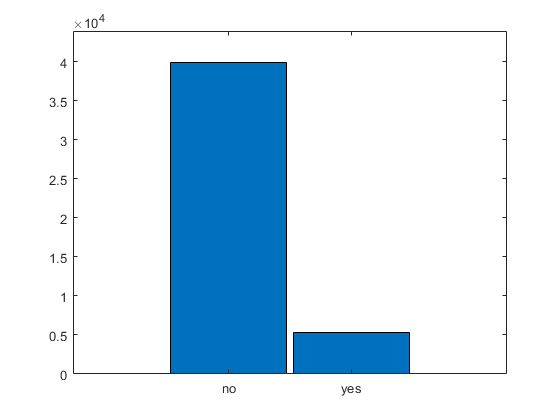

figure
hist(Y)

## 4. Partition Data

Partition the data so that 60% is used for training and 40% for validation.

cv = cvpartition(height(bank),'holdout',0.40);

Training set

Xtrain = X(training(cv),:);
Ytrain = Y(training(cv),:);

Test set

Xtest = X(test(cv),:);
Ytest = Y(test(cv),:);

## 5. Train classifier

Create a Discriminant Analysis classification model with the training data.

da = fitcdiscr(Xtrain,Ytrain);

## 6. Predict

Predict the class for the validation data and determine the validation error.

Ypred = predict(da,Xtest); 
misclassrate = loss(da,Xtest,Ytest);
disp(['Validation error for ensemble: ',num2str(misclassrate)])

Validation error for ensemble: 0.098276


## 7. Evaluate classification

Evaluate the classification by constructing a confusion matrix and visualize the groupings.

c = confusionmat(Ytest,Ypred)

c =        15330         602
        1207         945


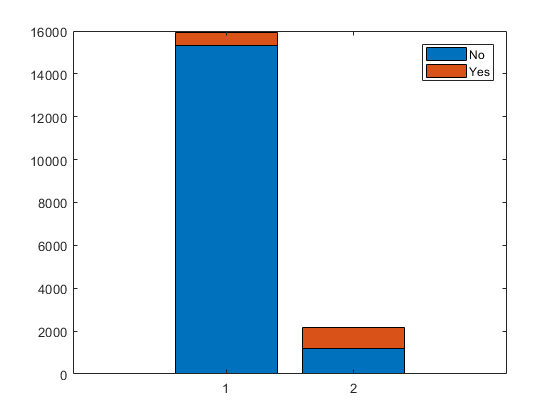


figure
bar(c,'stacked')
legend('No','Yes')